# PART 1

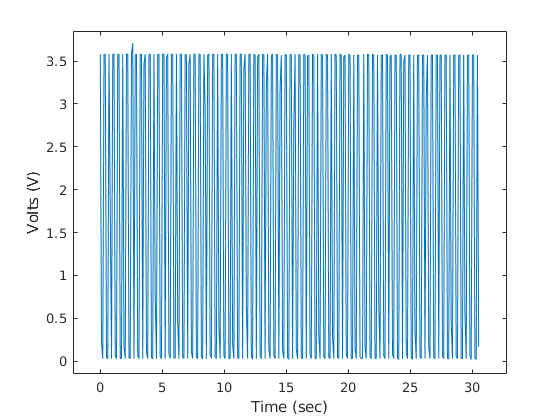


% read data example: Import columns as column vectors 
data = csvread('newfile.csv');%, 'columns', {'X, 'Y', 'Z'});

% Plot the imported data and label the graph correctly
time = data(:,1) ./ 1000;
volts = data(:,2);
figure(1)
plot(time,volts)
xlabel('Time (sec)')
ylabel('Volts (V)')

xlim([-2.2 32.8])
ylim([-0.15 3.85])


% Use findpeaks function and create new time_peaks array for plotting
[pks,locs] = findpeaks(data(:,2)');
time_peaks = [];
for e = locs
    time_peaks = [time_peaks time(e)];
end
 
% Frequency of time peaks
freq = 1/mean(diff(time_peaks))

freq = 2.7231

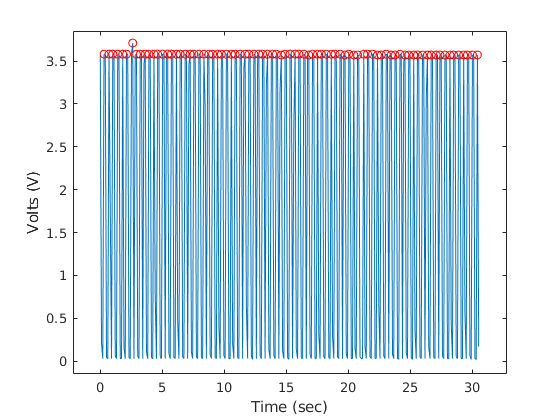


% Plot peaks with original plot
figure(2)
plot(time,volts)
xlabel('Time (sec)')
ylabel('Volts (V)')
xlim([-2.2 32.8])
ylim([-0.15 3.85])
hold on
plot(time_peaks,pks, 'or')




%%%%%%%%%%%%%%%%%%%%%% Using FFT %%%%%%%%%%%%%%%%%%%%%
figure(3)
L = size(time,1);             % Length of signal
plot(time, volts)
Fs = 1/mean(diff(time));

freq = 9.9289

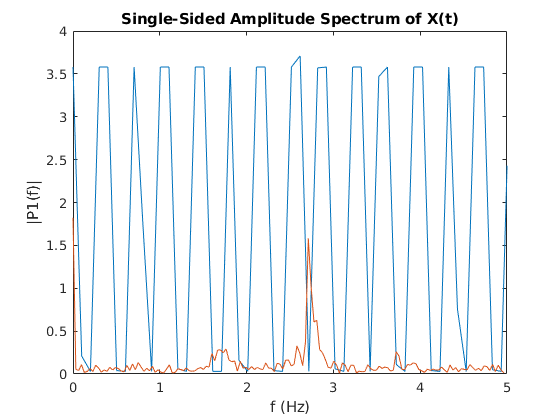


Y = fft(volts);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
hold on
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
xlim([0 5]) %fits axis so that peak x-values are identifiable
ylabel('|P1(f)|')